### Sistema massa molla smorzatore nonlineare

Consideriamo sistema massa molla smorzatore non lineare:


$$\begin{cases}
\dot{x}_1 =x_2 \\
\dot{x}_2=-\frac{k(x_1)}{m}-\frac{b(x_2)}{m} 
\end{cases}$$


dove $x_1 \left(t\right)=s\left(t\right)\;,x_2 \left(t\right)=\dot{\;s\;} \left(t\right)$, la costante elastica della molla è $k\left(x_1 \right)=k_0 x_1 +k_1 x_1^{3\;}$mentre la costante di attrito viscoso dello smorzatore risulta $b\left(x_2 \right)={\textrm{bx}}_2 \;\left|x_2 \right|$.

Assumendo ${m=k}_0 =k_1 =b=1$, il phase portrait per u=0 di tale sistema risulta:

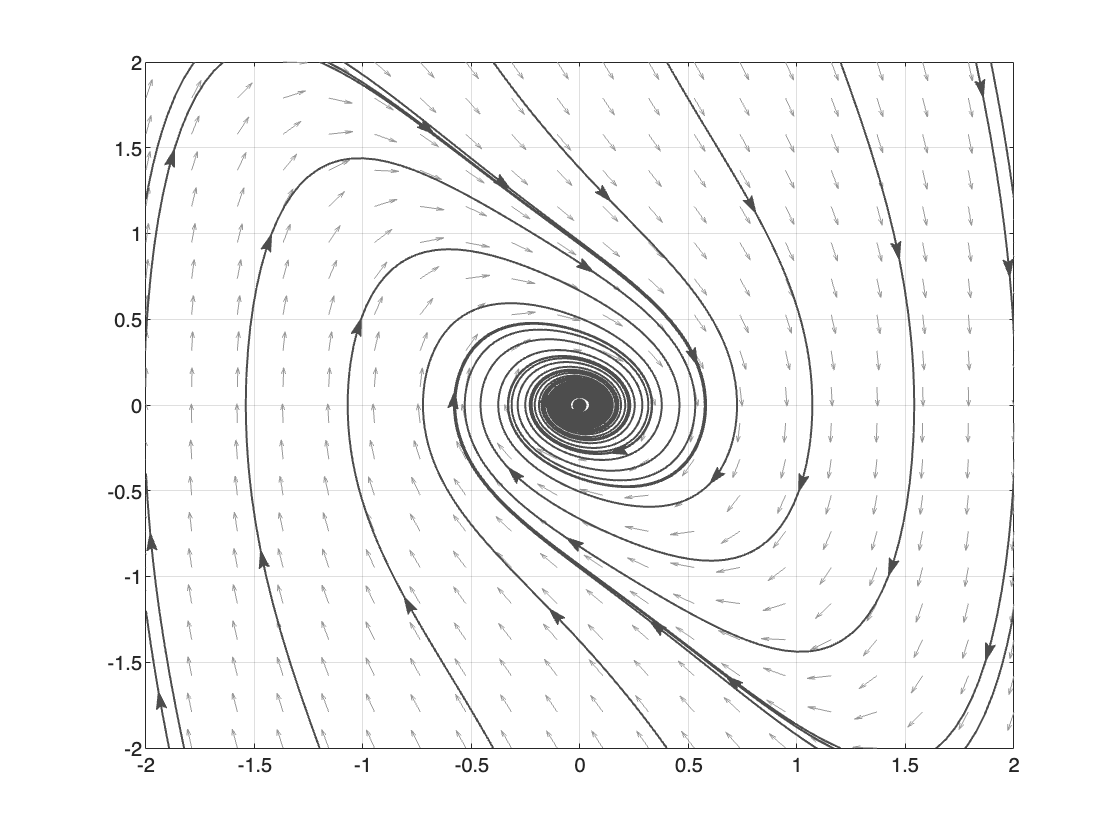


m=1;
k0=1;
k1=1;
b=1;
odefun = @(t, x) [x(2); -k0/m*x(1)-k1/m*x(1)^3-b*x(2)*abs(x(2))];
plotpp(odefun,'tspan', 50,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3],...
                      'xlim', [-2, 2], 'ylim', [-2, 2])

Tale sistema presenta un punto di equilibrio 

 $\bar{\;x\;} =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \;$.

Tale grafico mostra che tale punto di equilibrio è localmente asintoticamente stabile.

Di seguito proveremo a dimostrare la stabilità di tali punti di equilibrio mediante approccio linearizzato e di Lyapunov. 

**APPROCCIO BASATO SU MODELLO LINEARIZZATO**

Il modello linearizzato di tale sistema presenta una matrice dinamica pari a 


$$A={\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k_0 }{m}-3\frac{k_1 }{m}x_1^2  & -\frac{2b}{m}\left|x_2 \right|
\end{array}\right\rbrack }_{\bar{\;x\;} =\left\lbrack 0\;\;0\right\rbrack } =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k_0 }{m} & 0
\end{array}\right\rbrack$$


Gli autovalori di tale matrice risultano pari a 



A=[0 1 ; -k0/m 0];
eig(A)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i


Con un phase portrait

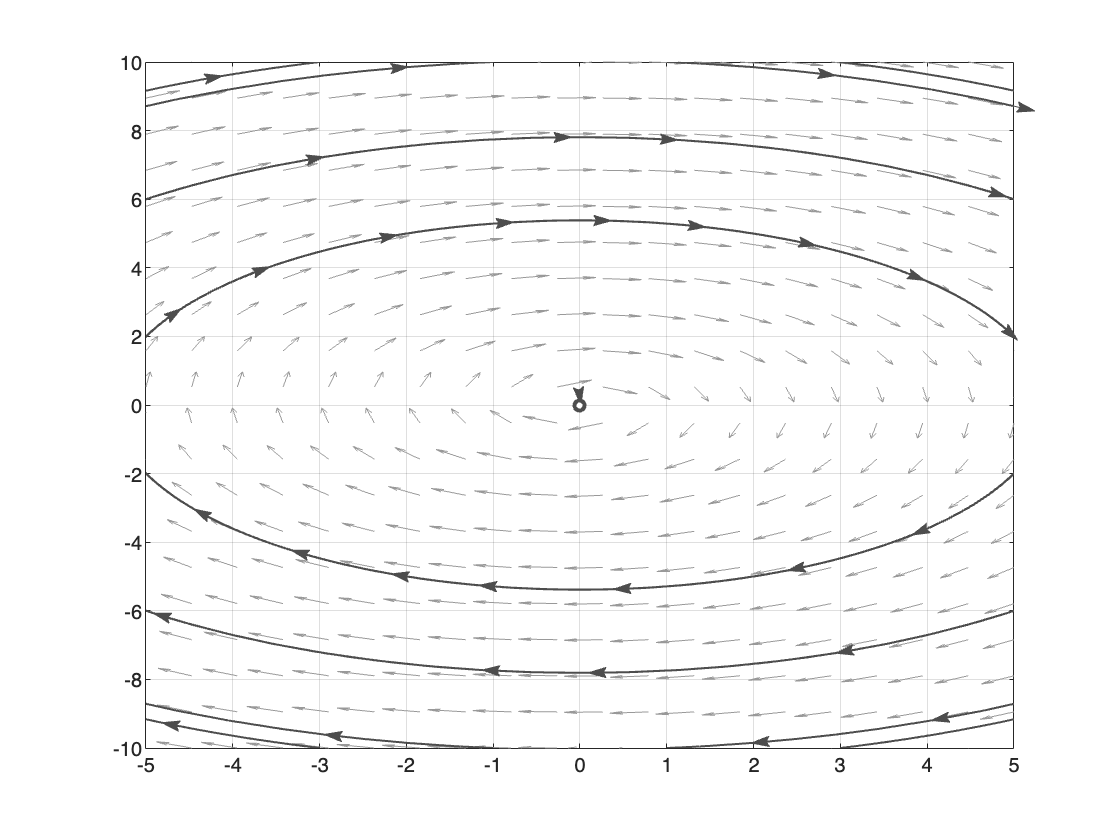


figure
odefun = @(t, x) [A(1,1)*x(1)+A(1,2)*x(2); A(2,1)*x(1)+A(2,2)*x(2)];
plotpp(odefun,'tspan', 50,...
                      'quivercolor', [0.6,0.6,0.6],...
                      'linecolor', [0.3,0.3,0.3],...
                      'xlim', [-5, 5], 'ylim', [-10, 10])

**Il sistema linearizzato non può essere utilizzato per determinare le proprietà di stabilità del punto di equilibrio in quanto la matrice ha autovalori a parte reale nulla.**

**APPROCCIO ALLA LYAPUNOV**

Assumendo una funzione di Lyapunov associata ad energia cinetica e potenziale del sistema:


$$V\left(x\right)=\frac{1}{2}{\textrm{mx}}_2^{2\;} +\frac{1}{2}k_{0\;} x_1^2 +\frac{1}{4}k_1 x_1^4$$


è possibile verificare falicmente che tale funzione è definita positiva in x=[0 0]

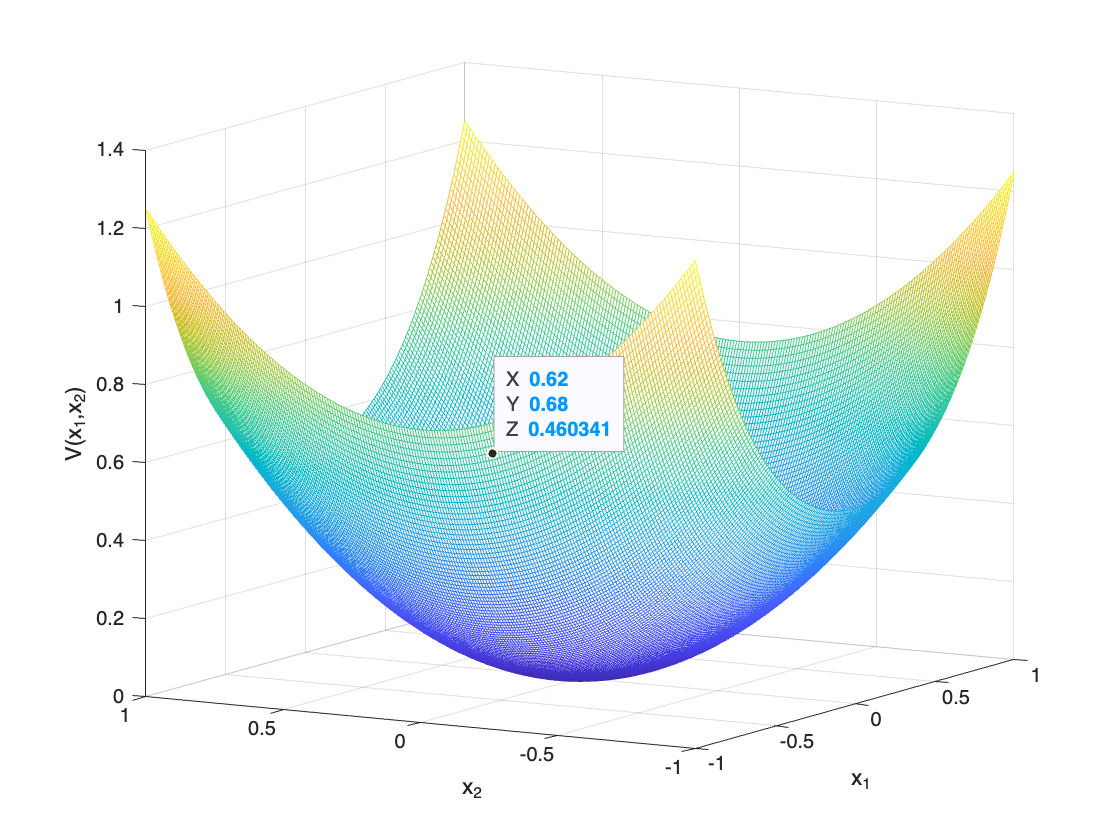


x1=-1:.01:1;
x2=x1;
[X1,X2]=meshgrid(x1,x2);
V=1/2*m*X2.^2+1/2*k0*X1.^2+1/4*k1*X1.^4;
figure
mesh(X1,X2,V);
xlabel('x_1')
ylabel('x_2')
zlabel('V(x_{1},x_{2})')

La derivata di tale funzione di Lyapunov risulta:


$$\dot{\;V} \left(x\right)=-b{\left|x_2 \right|}^3$$


Tale derivata è semidefinita negativa in x=[0 0] poichè si annulla in ogni punto $\left\lbrack \alpha \;\;\;0\right\rbrack ,\;\;$come mostrato dal seguente grafico

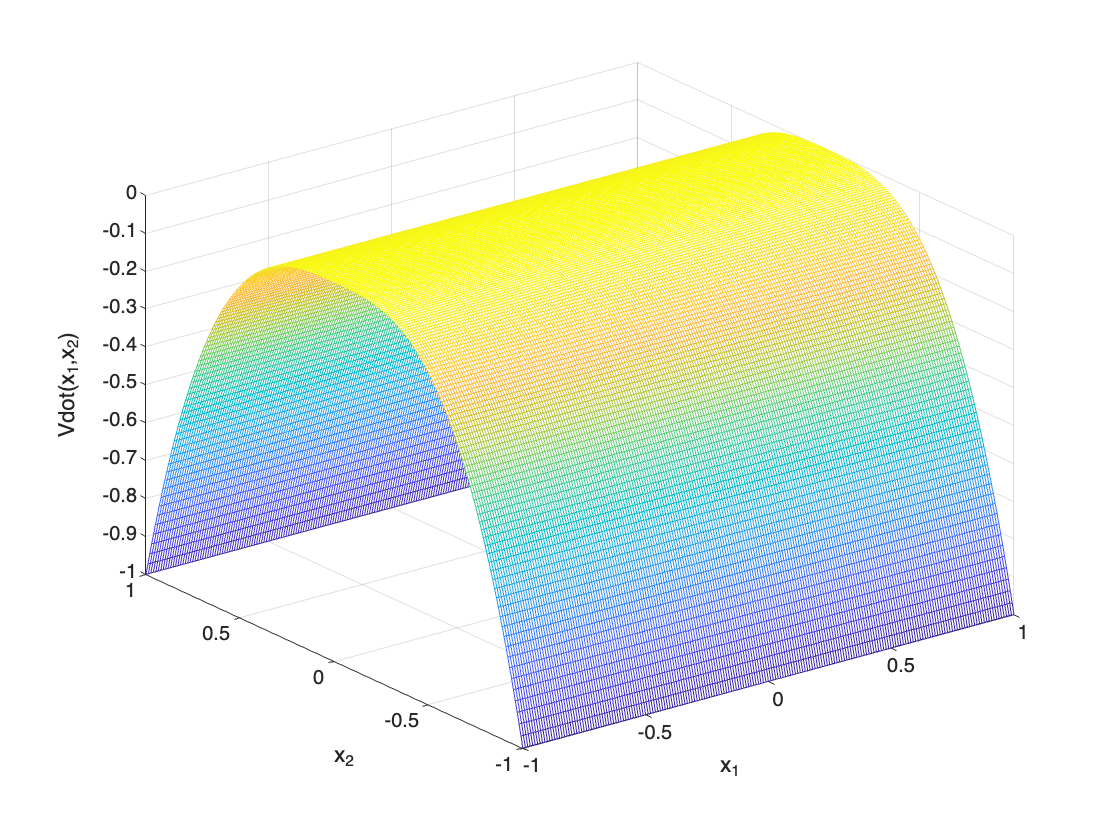

Vdot=-b*abs(X2.^3);
figure
mesh(X1,X2,Vdot);
xlabel('x_1')
ylabel('x_2')
zlabel('Vdot(x_{1},x_{2})')

Quindi, utilizzando il teorema di Lyapunov, è possibile dimostrare che il punto di equilibrio è localmente stabile, ma non asintoticalmente.

Utilizzando invece il Lemma di Krasowsky-La Salle, si nota come l'insieme S(x) in cui si annulla $\dot{\;V} \left(x\right)$ contiene solo l'origine come punto di partenza da cui le traiettorie del sistema rimangono in S(x). Quindi il punto di equilibrio è asintoticamente stabile. 